# General interactive user guide for GSUA-CSB Toolbox

Global Sensitivity and Uncertainty Analysis - Confidence Subcontour Box (GSUA-UCI) Toolbox is a product developed by [Universidad EAFIT](http://www.eafit.edu.co/international/eng/Paginas/eng.aspx) for command-line mathematical model validation in both of [Simulink](https://www.mathworks.com/products/simulink.html) or [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) environment . At present time, the toolbox allows to perform the following functions: To apply and visualize several variance-based sensitivity (SA) and uncertainty (UA) analysis, to estimate model parameters (PE) and to to estimate confidence subcontour boxes (CSB) for estimated parameters.. This toolbox is based on the previous work of [Carlos Mario Vélez](https://www.researchgate.net/profile/Carlos_Velez_S2):  GSUA of dynamical systems using variance-based methods, published in this [mathworks file exchange](https://www.mathworks.com/matlabcentral/fileexchange/47758-global-sensitivity-and-uncertainty-analysis-gsua-of-dynamical-systems-using-variance-based-methods) link.

#### Developers

- Daniel Rojas Díaz - drojasd@eafit.edu.co

- [Carlos Mario Vélez Sánchez](http://www.eafit.edu.co/docentes-investigadores/Paginas/carlos-mario-velez-sanchez.aspx) - cmvelez@eafit.edu.co

#### Addtitonal resources

Toolbox paper, Slides on UA/SA, model identifiability paper.

**IMPORTANT NOTE: **If you lost any of the results in this guide, you can recover it easy with the following command:

## Initial configuration

### Working with Simulink models

It is necessary to create and configure a simulink model as indicated in GSUA Simulink userguide. Also, check the guide for additional configurations.

### Working with Symbolic math models

It is necessary to create a system of equations as indicated in GSUA Symbolic Math userguide. Also, check the guide for additional configurations.

### Working with User-defined models

It is necessary to create a system of equations as indicated in GSUA Symbolic Math userguide. Also, check the guide for additional configurations.

## Toolbox routines for selected model

For the following examples we will use a symbolic math model (same as constructed in  GSUA Symbolic Math userguide). You can execute your own model or the Simulink model example following the respective userguide steps.

###  1. Simulating the model

%load default example model
default_example

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccc} R\left(t\right) & S\left(t\right) & \text{I}\left(t\right) & \beta & \gamma \end{array}\right)$$

T%check the summary table

T = 4×2 table
                Range       Nominal
             ___________    _______

    S0       100    3000      1550 
    I0         1     500     250.5 
    beta       0       1       0.5 
    gamma      0       1       0.5 


#### 1.1 gsua_eval function

help gsua_eval%check features

  Function for few model evaluations
  
  Y=gsua_eval(values,Table)
  Parameters:
  values <-- array of NpxN (number of factors x number of simulations)
  Table  <-- summary table from gsua_dataprep function
  Outputs:
  Y <-- array with model output
  Additional features:
  If you provide an array (xdata) that belongs to the model domain, then
  the model output is interpolated to match xdata. Also you can provide a
  previous model output or experimental data as an array (ydata) that must
  coincide with the xdata array:
  Y=gsua_eval(values,Table,xdata,ydata)



Execute the following line to modify the number of model outputs (valid only for symbolic math and user-defined models)

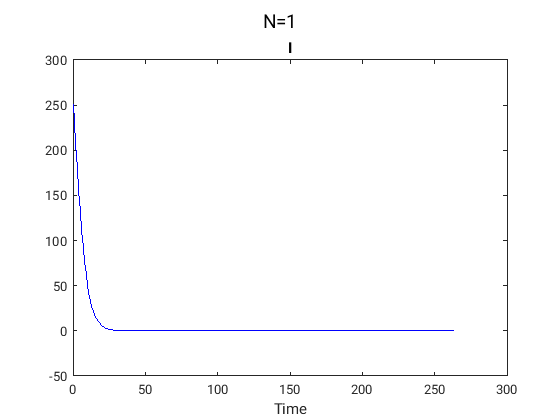

y=gsua_eval(T.Nominal,T);% simple simulation with factor values stored in T.Nominal
%now, we are going to use the additional features of the function
xdata=linspace(0,264,265);%create 265 points between 0 and 264
noise= normrnd(0,0.2,size(xdata));%create noise
%simulate the model with user defined parameters and return values in xdata
y=gsua_eval([1000 200 0.1 0.06]',T,xdata);

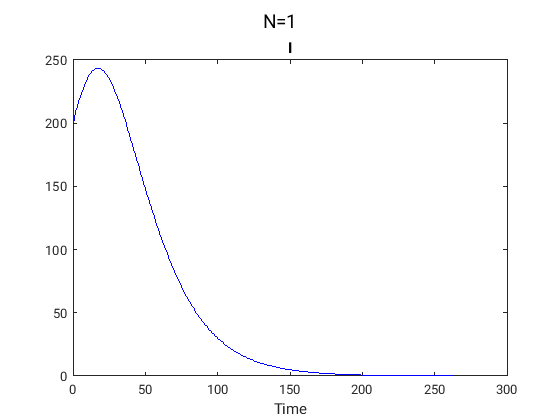

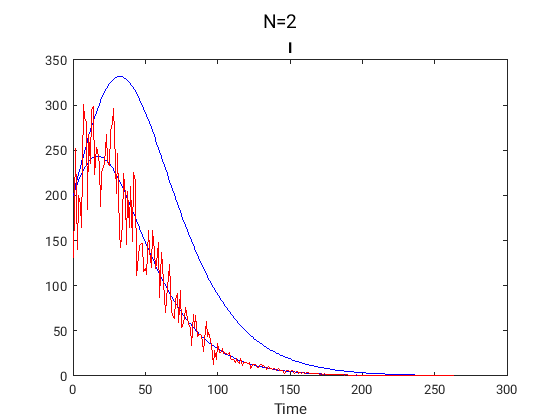

yexp=y+y.*noise;%create a noisy output
%compare results and simulate another factors family
y=gsua_eval([1000 200 0.1 0.06; 2000 200 0.1 0.06]',T,xdata,yexp);

### 2. Sample the space of factors

#### 2.1 gsua_dmatrix function

help gsua_dmatrix

  Function for design of experiments (factor space sampling)
 
  [M,T2]=gsua_dmatrix(T,N)
  Parameters:
  T <-- summary table from gsua_dataprep
  N <-- number of samples
  Outpus:
  M  <-- design matrix of NxNp for later routines
  T2 <-- summary table with fixed parameters actualized
  Additional features:
  You can choose a method for factor space sampling between uniform
  distribution design and latin hypercube design (default). To switch
  between methods use the paired feature 'Method' and 'Uniform' or
  'LatinHypercube'.
  Also you can visualize the sampling result using the paired feature
  'Show', 'on'
  M=gsua_dmatrix(T,N,'Method','Uniform','Show','on')



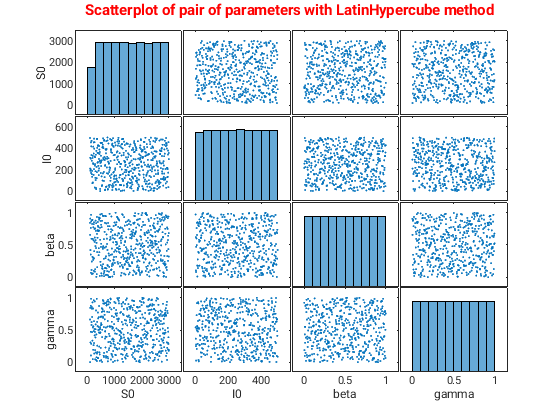

M=gsua_dmatrix(T,500,'Show','on');%design matrix with 500 samples

%we ignore T2 because there is no new fixed parameters

### 3. Uncertainty analysis

#### 3.1 gsua_ua function

help gsua_ua

  Function for uncertainty analysis
 
  Y=gsua_ua(M,T)
  Parameters:
  M <-- design matrix from gsua_dmatrix function
  T <-- summary table from gsua_dataprep function
  Output:
  Y <-- result of Monte-Carlo simulation
  Additional features:
  The function automatically apply a Monte-Carlo filtering over results and
  present it as figures (gsua_MCF function). It is possible to perform UA
  over multiple model outputs. To obtain extrapolated results, use the
  paired feature 'xdata'. To compare results with a specific output use
  the paired feature 'ynom' (ynom length must coindice with xdata length).
  To avoid parallel computing (no speed up), use the paired feature 
  'parallel',false.
  Y=gsua_ua(M,T,'xdata',xdata,'ynom',ynom,'parallel',false)



Progress: 100%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 2:31:45
Number of simulations: 500


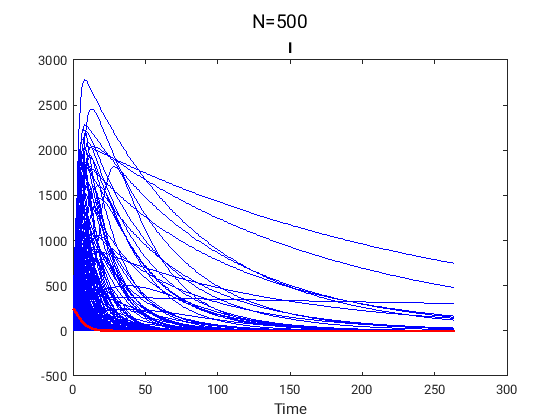

M=gsua_dmatrix(T,500);%design matrix
xdata=linspace(0,264,265);%265 points between 0 and 264
Y=gsua_ua(M,T,'xdata',xdata);

Since we do not specify a nominal output, the function will take as nominal the output associated with T.Nominal values (red line in first figure above).

The Monte-Carlo filtering interpretation is as follows:

- The bigger the difference between low values (blue) and high values (red) lines, the bigger is the factor relevance.

- If low values (blue) is the bottom line, then high values for the correspondent factor generates low values for model output and low values for the correspondent factor generates high values for model output..

- If high values (red) is the botton line, then high values for the correspondent factor generates hich values for model output and low values for the correspondent factor generates low values for model output.

%if you change ynom, then Monte-Carlo filtering results could vary
ynom=gsua_eval([1000 200 0.1 0.06]',T,xdata);

Progress: 100%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 2:31:50
Number of simulations: 500


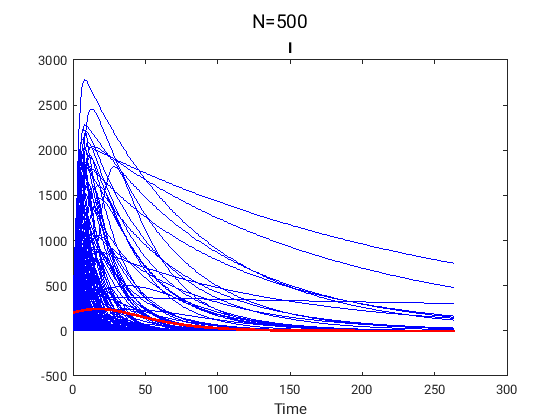

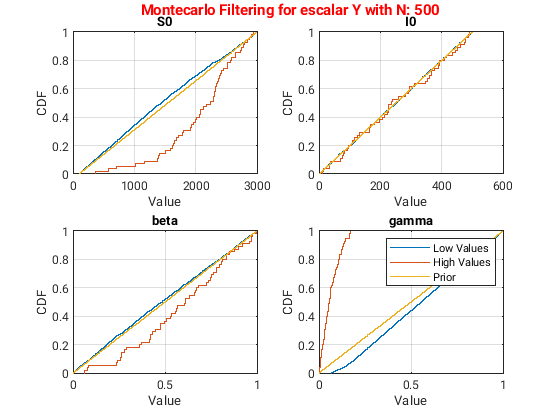

Y=gsua_ua(M,T,'xdata',xdata,'ynom',ynom);

Now, results interpretation is much more tricky. It is better to perform a SA (next section).

### 4. Sensitivity analysis (SA)

#### 4.1 gsua_sa function

Sensitivity indices estimators implemented in this toolbox are based on the following works:

[1]: Saltelli, A., Annoni, P., Azzini, I., Campolongo, F., Ratto, M., and Tarantola, S. (2010).  Variance based sensitivity analysis of model output. design and estimator for the total sensitivity index. Computer Physics Communications, 181(2):259–270.

[2]: Xiao, S., Lu, Z., and Wang, P. (2018). Multivariate global sensitivity analysis based on distance components decomposition. Risk Analysis, 38(12):2703–2721.

Saltelli method has been configured to work with Minimun Least-Squares outputs, if you do not provide a specific 'ynom' the function assume that 'ynom' is given by the nominal Factors in T.

Xiao method is especially good for time-dependent model responses.

help gsua_sa

  Function for sensitivity analysis
 
  T=gsua_sa(M,T)
  Parameters:
  M <-- design matrix from gsua_dmatrix function
  T <-- summary table from gsua_dataprep function
  Output:
  T <-- summary table with sensitivity indices.
  Additional features:
  It is possible to request 2 extra positional outputs:
  J <-- vector of model outputs in scalar representation (MSE)
  Y <-- model output matrix (same as gsua_ua output)
  It is possible to choose between 6 SA methods using the paired feature
  'SensMethod',method. Where method is one of the following:
  'Saltelli'    <-- requires N*(Np/2+1) simulations
  'Jansen'      <-- requires N*(Np/2+1) simulations
  'Xiao'        <-- newest method (Default), requires N*(Np/2+1)
                    simulations
  'Sobol'       <-- classic method, requires N*(Np+1) simulations
  'brute-force' <-- explores all possible combinations, N + Np2*N^2
                    simulations
  'OAT'         <-- non-global method, requires N*(Np+1) simu

Let's use the same M matrix as in previous section, without a specific ynom. Hence, the toolbox will take as ynom the output associated to T.Nominal values. Sensitivity indices are not affected by ynom selection. Additional outputs J and Y will be used for posterior analysis.

[T,J,Y]=gsua_sa(M,T,'SensMethod','Xiao');

Progress: 17%
Estimated processing time (h:m:s): 0:0:5
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 2:32:11
Number of simulations: 1500
Progress: 34%
Estimated processing time (h:m:s): 0:0:6
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 2:32:12
Number of simulations: 1500
Progress: 50%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:4
Estimated stop time (h:m:s): 2:32:14
Number of simulations: 1500
Progress: 67%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:3
Elapsed time (h:m:s): 0:0:6
Estimated stop time (h:m:s): 2:32:15
Number of simulations: 1500
Progress: 84%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:8
Estimated stop time (h:m:s): 2:32:15
Number of simulations: 1500
Progress: 100%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:

#### 4.2 SA results visualization and interpretation

- `gsua_plot('UncertaintyAnalysis',T,Y,xdata,ynom); ``<- Uncertainty analysis graph`

- `gsua_plot('ScatterOutput',T,Y,M,xdata,xref); ``<- Uncertainty analysis for output in time=xref`

- `gsua_plot('ScatterOutput',T,J,M,xdata); ``<- Uncertainty analysis for scalar output (MSE of the output with respecto to ynom)`

- `gsua_plot('Pie',T,T.STi/Si); ``<- Pie graph of sensitivity indices`

- `gsua_plot('Bar',T,T.STi/Si); ``<- Bar graph of sensitivity indices`

- `gsua_plot('FractionalSensitivityArea',T,T.STi_vec/Si_vec,xdata); ``<- Area graph of vectorial sensitivity indices (a index for each point in xdata)`

- `gsua_plot('TotalSensitivityArea',T,T.STi_vec/Si_vec,xdata); ``<- Normalized area graph of vectorial sensitivity indices (a index for each point in xdata)`

- `gsua_plot('FractionalSensitivityPlots',T,T.STi_vec/Si_vec,xdata); ``<- Figure of subgraphs with the sensitivity indices plot for each factor, and for each point in xdata.`

- `gsua_plot('Pie',T,T.STi_vec/Si_vec,xdata,[t1,t2,t3,t4]); ``<- Figure of pie subgraphs. As many subgraphs as points in [t1,t2,...tn]. Each pie represent the sensitivity indices for a specific time [t1,t2,...tn].`

The most relevant index to assess parameter relevance is **STi**. However, it is neccesary to point out a relevant feature about the indices: The summatory of **STi** is always greater or equal to one, while the summatory of **Si **is always lesser or equal to one. If one of the sumatories is equal to one, the other one must be equal too, and hence, the model is purely additive.

A general advice is to perform a global SA over the model when the interaction among factors it is unknown. If the summatory of **Si **is greater than 0.65, then you can state that the model has weak interactions among factors and said interactions are negligible. Thereby, for subsequent analysis, it is better to perform local SA analysis or analytical SA methods.

**IMPORTANT NOTE: **Choosing an appropriate N for SA is a challenging task. However, Saltelli and Distance method allow an aproximation: A good N has been chosen when there are no negative **Si**. Thereby, if you get negative **Si **values, you should consider to probe with a greater N.

T.Si

ans =     0.1699
    0.0220
    0.0456
    0.6895


sum(T.Si)

ans = 0.9270

sum(T.STi)

ans = 1.2884

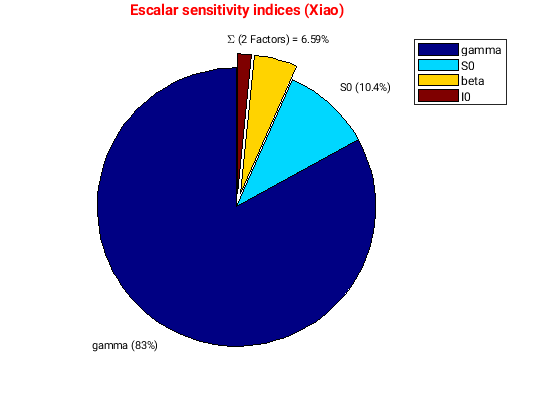

clf
gsua_plot('Pie',T,T.STi)
colormap jet

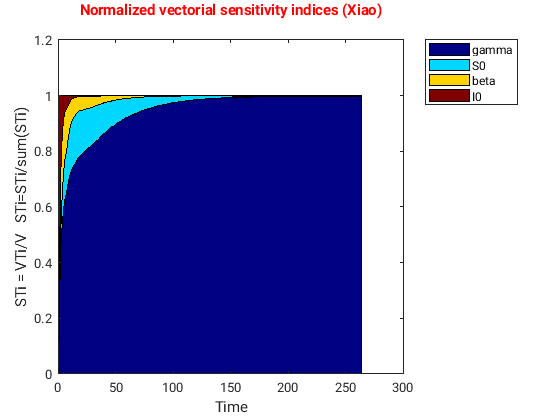

clf
gsua_plot('TotalSensitivityArea',T,T.STi_vec,xdata);
colormap jet

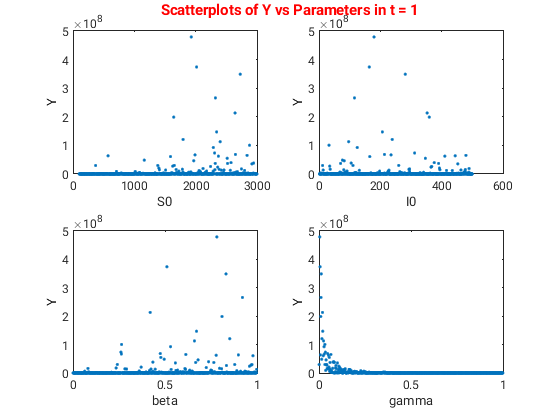

clf 
gsua_plot('ScatterOutput',T,J,M,xdata);

### 5. Parameter estimation

#### 5.1 gsua_pe function

help gsua_pe

  Parameter estimation function
  [T,res] = gsua_pe(T,xdata,ydata,N)
  Parameters:
  T     <-- summary table from gsua_dataprep function
  xdata <-- array of points where the model will be evaluated
  ydata <-- array with expected model output
  Outputs:
  T   <-- summary table with parameter estimation results
  res <-- cost functions for each estimation
  Additional paired features:
  'N',N     <-- number of parameter estimations
  'Multistart',k <-- activate multistart feature for lsqcurvefit optimizer,
  perform k parameter estimations in each cycle
  'solver',{'lsqc','lsqn','ga','particle','psearch','surrogate','annealing'}
  <-- allows to choose among several matlab optimizers. Default: lsqc
  'opt',optimoptions(optimizer,...) <-- allows to configure the respective
  matlab optimizer, optimizer must match with the real matlab optimizer
  name.
  'ipoint',point <-- allows to give to the optimizer the initial points for
  estimations. point must have the same numbe

Generating a valid matrix for estimations


Estimation 1

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>
Estimation 2

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

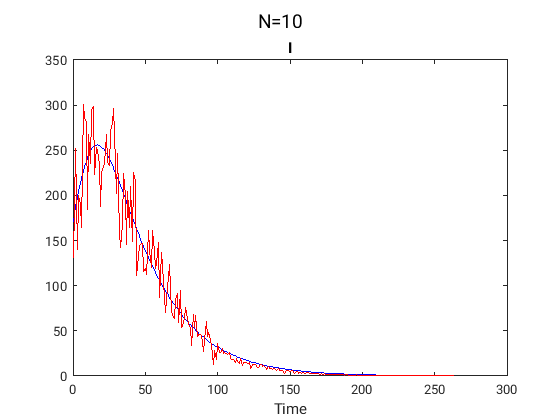

solver='lsqc';%this is the default solver
opt=optimoptions('lsqcurvefit','UseParallel',true);%configure optimizer
[T,res]=gsua_pe(T,xdata,yexp,'solver',solver,'Show','on','opt',opt,'N',10);

T%look the actual table, there is a lot of information

T = 4×7 table
                Range       Nominal       Si         STi          STi_vec            Si_vec           Estlsqc   
             ___________    _______    ________    ________    ______________    ______________    _____________

    S0       100    3000      1550      0.16987     0.13389    [1×265 double]    [1×265 double]    [1×10 double]
    I0         1     500     250.5     0.021958    0.021405    [1×265 double]    [1×265 double]    [1×10 double]
    beta       0       1       0.5     0.045633    0.063488    [1×265 double]    [1×265 double]    [1×10 double]
    gamma      0       1       0.5      0.68954      1.0696    [1×265 double]    [1×265 double]    [1×10 double]


#### 5.2 Identifiability analysis

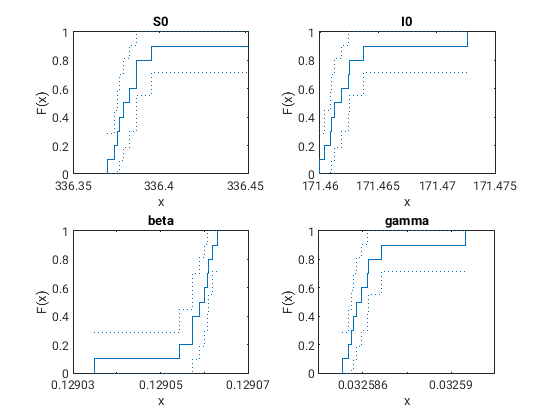

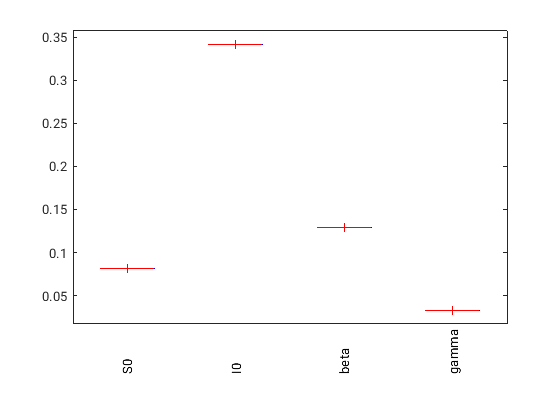

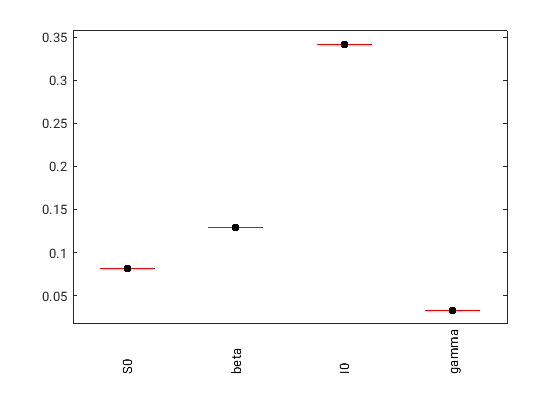

T_newRange = 4×7 table
                    Range            Nominal        Si         STi          STi_vec            Si_vec           Estlsqc   
             ____________________    ________    ________    ________    ______________    ______________    _____________

    S0         336.37      336.45      336.37     0.16987     0.13389    [1×265 double]    [1×265 double]    [1×10 double]
    I0         171.46      171.47      171.46    0.021958    0.021405    [1×265 double]    [1×265 double]    [1×10 double]
    beta      0.12903     0.12906     0.12906    0.045633    0.063488    [1×265 double]    [1×265 double]    [1×10 double]
    gamma    0.032585    0.032591    0.032585     0.689

T_newRange=gsua_ia(T,T.Estlsqc)

### 6. Uncertainty Interval Calculus

#### 6.1 gsua_oatr function

help gsua_oatr

  Function for once-at-time ranges expantion
 
  T=gsua_oatr(T)
  Parameters:
  T <-- summary table from gsua_dataprep function. The objective output is
  given by T.Nominal.
  Outputs:
  T <-- summary table with new factor intervals in T.Range
  Additional features:
  To define limit for range expantion use the paired feature 'lim'.
  Default:0.3.
  To speed up range calculus, use the paired feature 'parallel',true.
  T=gsua_oatr(T,'lim',0.2,'parallel',true)



Expansion-reduction Method OAT is being launched
------------------------------------
Calculus of gamma Starting
Activating intern_counter for gamma
Activating intern_counter for gamma
Range for gamma Done!
Initial range of gamma(4)--> 0  1
Actual range --> 0       0.135
Calculus of beta Starting
Activating intern_counter for beta
Activating intern_counter for beta
Range for beta Done!
Initial range of beta(3)--> 0  1
Actual range --> 0       0.225
Calculus of I0 Starting
Range for I0 Done!
Initial range of I0(2)--> 1  500
Actual range --> 137.375      265.5931
Calculus of S0 Starting
Activating intern_counter for S0
Activating intern_counter for S0
Range for S0 Done!
Initial range of S0(1)--> 100  3000
Actual range --> 0  2250


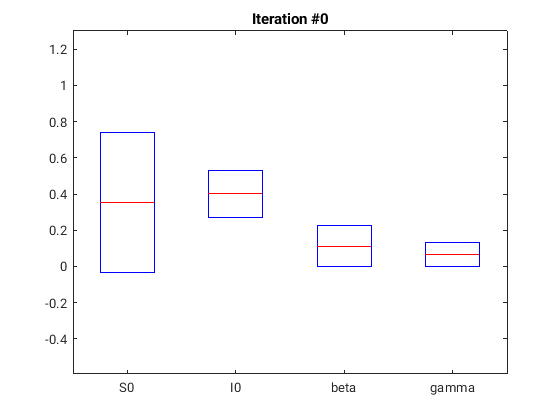

T_oat = 4×7 table
                  Range          Nominal       Si         STi          STi_vec            Si_vec           Estlsqc   
             ________________    _______    ________    ________    ______________    ______________    _____________

    S0            0      2250     1000       0.16987     0.13389    [1×265 double]    [1×265 double]    [1×10 double]
    I0       137.37    265.59      200      0.021958    0.021405    [1×265 double]    [1×265 double]    [1×10 double]
    beta          0     0.225      0.1      0.045633    0.063488    [1×265 double]    [1×265 double]    [1×10 double]
    gamma         0     0.135     0.06       0.68954      1.0696    [1×265 double]   

T.Nominal=[1000 200 0.1 0.06]';
T_oat=gsua_oatr(T)

#### 6.2 gsua_ucis function

Please, do not execute **gsua_csb** function inside live script environment.

help gsua_csb

  Function for uncertainty-based confidence intervals
 
  T= gsua_csb(T,N)
  Parameters:
  T <-- summary table from gsua_oatr function
  N <-- Number of samples per cycle
  Outputs:
  T <-- summary table with new confidence intervals in T.Range
  Additional features:
  It is possible to request the following additional positional outputs
  New_range <-- array with range modification record.
  J_test <-- MSE output of last iteration
  Y_test <-- output of last iteration
  sup    <-- record of good scalars
  Also, it is possible to apply the next paired features
  'ynom',ynom <-- to especify a new output objective
  'reps',k <--to perform k cycles. Default: 100.
  'recort',r <-- to set another recort criteria (r). Default: 0.5.
  'select',s <-- to set another select criteria (s). Default: 0.5.
  'lim',l <-- to set another distance criteria (l). Default: 0.3.
  'stop',p <-- to set the confidence of the interval in (p). Default: 0.95.
  'parallel',false <-- to avoid the sp

Execute the following in matlab command window

# Interactive user guide for Toolbox initial configuration (Simulink)

We will use a preconfigured predator - prey model (order: 2, factors: 5) as example throughout the present guide. To acces the model, type:

## **1. Model preparation**

It is advisable to create a mask for factor (input, parameter or initial condition) value assignation. However, it is not necessary.

                  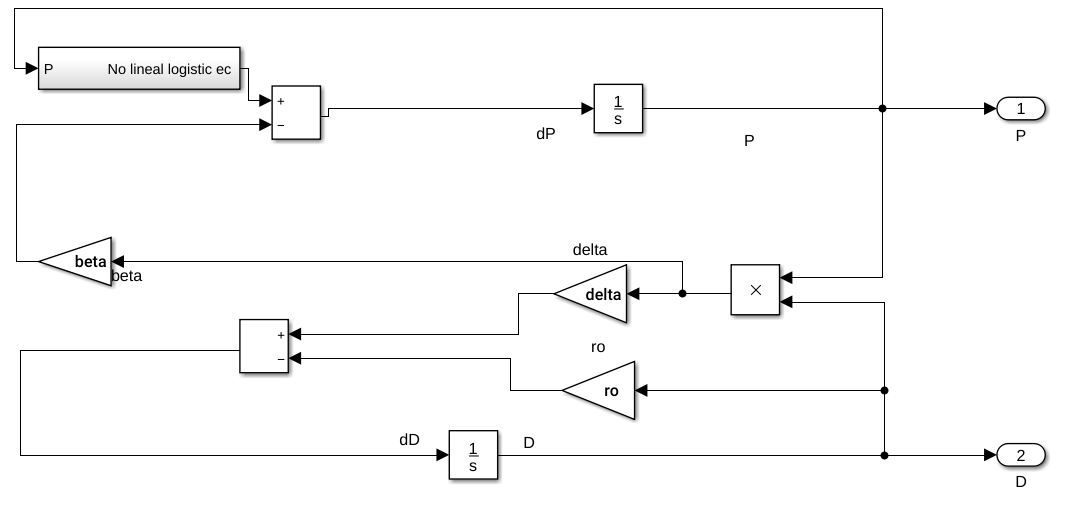    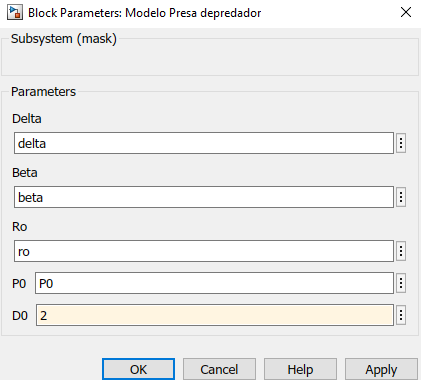

It is fundamental to assign the value of each factor as a reference to some variable in the Model workspace, it is necessary because the toolbox will identify and assign values for the factors by name matching. If you want to exclude a factor for the analysis, you must to assign it a constant value insted of a reference name. As you can see in the previous figures, the predator-prey model has 5 factors, and we will use all of them but D0 for analysis. If you have preferred a configuration, apply it to the model (use the Model configuration Parameters option, redbox in next figure), otherwise, the toolbox will apply the Simulink current configuration.

At the moment, it is possible to work only with a single model output, hence, you must to connect an **output block** to the objective output and a **terminator block** for any other output, as shown in following figure.

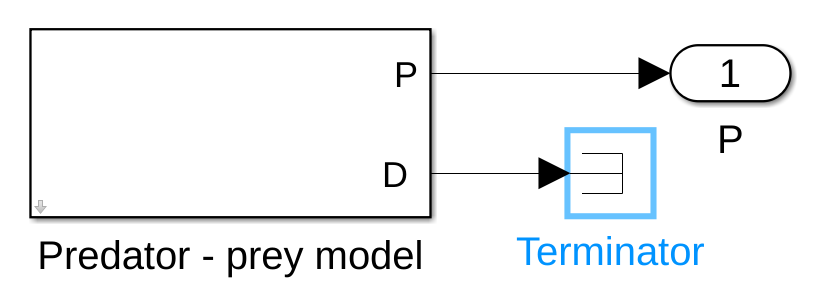

For this example, we will apply analysis over prey population (P).

**Resources:**

[Simulink masks - MathWorks ](https://la.mathworks.com/help/simulink/ug/how-to-mask-a-block.html)

[Espacio de estado y simulación - spanish slides](https://drive.google.com/file/d/0BwXJdRHn-Rd6UW90cEVFTEpEd28/view)

## 2. Environment configuration and additional features

Parameters:

- model: file name of the simulink model

- Ranges: Npx2 array or cell array with the range of Np factors (see additional features)

- ParIn: cell array with the factor names of the model

Outputs:

- T: table array with all required system information

-  tout: array of output time for the model

model='predatorprey';

Setting environment to work with simulink
Setting nominal values
All done!


T = 4×2 table
               Range       Nominal
             __________    _______

    beta     0.4    0.6      0.5  
    delta    0.4    0.6      0.5  
    ro       2.2    2.8      2.5  
    P0       2.7    3.2     2.95  


time =     1.0000
    1.1000
    1.2000
    1.3000
    1.4000
    1.5000
    1.6000
    1.7000
    1.8000
    1.9000


ParIn={'beta','delta','ro','P0'};
Ranges=[0.4 0.6; 0.4 0.6; 2.2 2.8; 2.7 3.2];
[T,time] = gsua_dataprep(model,Ranges,ParIn)

### 2.1 Additional features:

#### 2.1.1 Range definition 

**Paired feature 'rMethod' (default: range)**

You can choose between 4 methods to define the ranges of the model factors, each method requires a different definition of varible **Ranges**

- std        <-- {Nominal value,  Distance to interval limits}

- percent <-- {Nominal value,  percent of distance to interval limits}

- range    <-- {Inferior limit, superior limit}

- normal  <-- {Nominal value,  standart deviation}

Examples:

**Note: **The use of normal distribution affects the generation of samples from the space of factors when using the **gsua_dmatrix **function.

**A 'rMethod' for each single range (do not use normal rMethod)**

You can define a different **rMethod** for each factor range. To do this, just add a third column to **Range** array and specify the **rMethod **there.

Example:

#### 2.1.2 Nominal factor family

You can specify a nominal family of factor values using the **paired feature 'nominal'**. It could be useful for some toolbox functions.

Example:

#### 2.1.3 Model kind (default: Dynamic)

It is possible to work with static models in simulink (initial time = final time = 0). To active the configuration for static models use the **paired feature 'modelkind'**

Example:

#### 2.1.4 Fixed step (Default: [])

It is possible to specify from the toolbox a fixed-step magnitude for the model using the **paired feature 'Step'**

Example: 

Return to main page

Go to next toolbox features

# Interactive user guide for Toolbox initial configuration (Symbolic Matlab)

We will create and configure a simple SIR model with Symbolic Math Toolbox

## 1. Model creation

syms S(t) I(t) R(t) P(t) beta gamma P %symbolic state variables and parameters
P=S+I+R;
%Defining the system of differential equations
ode1 = diff(S) == -S*I*beta/P;
ode2 = diff(I) == S*I*beta/P - gamma*I;
ode3 = diff(R) == gamma*I;
%Array with the system
odes=[ode1; ode2; ode3]

$$odes(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}S\left(t\right)=-\sigma_{1}\\ \frac{\partial }{\partial t}\text{I}\left(t\right)=\sigma_{1}-\gamma \,\text{I}\left(t\right)\\ \frac{\partial }{\partial t}R\left(t\right)=\gamma \,\text{I}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\beta \,\text{I}\left(t\right)\,S\left(t\right)}{\text{I}\left(t\right)+R\left(t\right)+S\left(t\right)} \end{array}$$

%choose an order for state variables
vars = [R S I];

If your model is in the form $\overset{\left(n\right)}{y} =f\left(t,y,\dot{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n-1\right)}{y} \right)$ then use the the following command 

## 2. Environment configuration and additional features

Parameters:

- odes: array with the system of differential equations

- vars: array with state variables

- domain: 1x2 array with the range of the domain

- modelName: the function creates a file with the model for later simulations, modelName is the name for said output model file

Outputs:

- Table: table array with all required system information

- solver: function handle for simulations (not necessary)

**Use:**

Run the following to obtain the correct order for the factors

domain=[0 264];
modelName='SIR';
[T,solver]=gsua_dataprep(odes,vars,domain,modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccc} R\left(t\right) & S\left(t\right) & \text{I}\left(t\right) & \beta & \gamma \end{array}\right)$$

Now, you can manually add information to the Table **T** or use the following additional features:

### 2.1 Additional features

#### 2.1.1 Range definition

**Paired feature 'range' and 'rMethod' (Default rMethod: range)**

You can directly provide the range of model factors.

You can choose between 4 methods to define the ranges of the model factors, each method requires a different definition of varible **Ranges**

- std        <-- {Nominal value,  Distance to interval limits}

- percent <-- {Nominal value,  percent of distance to interval limits}

- range    <-- {Inferior limit, superior limit}

- normal  <-- {Nominal value,  standart deviation}

Examples:

**Note: **The use of normal distribution affects the generation of samples from the space of factors when using the **gsua_dmatrix **function.

Ranges=[0 0; 100 3000; 1 500; 0 1; 0 1];
[T,solver] = gsua_dataprep(odes,vars,domain,modelName,'range',Ranges)

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccc} R\left(t\right) & S\left(t\right) & \text{I}\left(t\right) & \beta & \gamma \end{array}\right)$$

T = 4×2 table
                Range       Nominal
             ___________    _______

    S0       100    3000      1550 
    I0         1     500     250.5 
    beta       0       1       0.5 
    gamma      0       1       0.5 


solver = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)


**Note: **To fix a factor, give to the function the respective range as a degenerated one (min=max). As you can see, fixed factors will not appear in table **T **(see previous table for R0 factor).

#### 2.1.2 Nominal factor family

You can specify a nominal family of factors values using the **paired feature 'nominal'**. It could be useful for some toolbox functions.

Example:

#### 2.1.3 Specific model output (Default: 1:model_order)

You can specify the output(s) of interest for the model as an array (it should be only one output for **SA, **and **UCI**) using the **paired feature 'output'**.

Example:

#### 2.1.4 Specific ode solver (Default: ode45)

You can choose between a fixed step solver (ode4) and an adaptative ode solver (ode45) to solve your model using the **paired feature 'solver'.**

Example:

#### 2.1.5 Ode solver configuration (Default: none)

You can configure the ode45 solver with all possible options (check [Matlab odeset](https://www.mathworks.com/help/matlab/ref/odeset.html)) using the **paired feature 'opt'.**

Example:

#### 2.1.6 Static model simulation

You can simulate static models defining the **domain **variable as a single number.

Example:

Return to main page

Go to next toolbox features

# Interactive user guide for Toolbox initial configuration (User-Defined functions)

**User defined functions must be stored as .m files. **

## 1. Time-dependent functions

### 1.1 Model creation

Time-dependent functions must be configured in the form **output=user_function(factors,domain)**. Where:

**Parameters:**

- factors: is a vector of parameters of **Np**x**N**, being **Np **the number of parameters and **N **the number of simulations to run (if vectorized, otherwise, **N=1)**. 

- domain: is a vector of **1**x**2** that represents the time domain for the simulation in the form **[initial_time, final_time]**

**Output:**

output is a struct() object with the following fields at least:

- output.x: simulation time.

- output.y: simulation outputs, as a matrix of **nOutputs**x**|output.x|**, where **nOutputs **is the number of outputs of the model and **|output.x| **is the length of the simulation time.

In this way, the outputs from matlab ode and dde solvers meet the requirements.

#### 1.1.1 Example

### 1.2 Model implementation

To prepare the environment to work with time-dependent user-defined functions, you must run the following code, replacing input parameters as indicated

Parameters:

- func: name of the .m file as char

- ranges: **Np**x**2** array with the range of the factors

- domain: **1**x**2** array with the range of the domain

Outputs:

- Table: table array with all required system information

- solver: function handle for simulations (not essential)

**Use: **

We will expose an example implementing the example function user_defined.m (defined above), you can use the command 

to access the function

func='user_dependent';
ranges=[0.1 0.3; 10 14];
domain=[0 25];
[T,sol]=gsua_dataprep(func,ranges,'domain',domain)

Setting environment to work with user-defined function


T = 2×2 table
           Range       Nominal
         __________    _______

    1    0.1    0.3      0.2  
    2     10     14       12  


sol = function_handle with value:
    @(pars)user_func(pars',domain)


Test if the model is actually working by running a simmulation with the values stored at T.Nominal

gsua_eval(T.Nominal,T);

Change the number of outputs (max 2) with the following command

T.Properties.CustomProperties.output=1:2;

Provide a specific xdata to achieve the model behaviour at those points

xdata=0:0.1:25;

Evaluate the model again

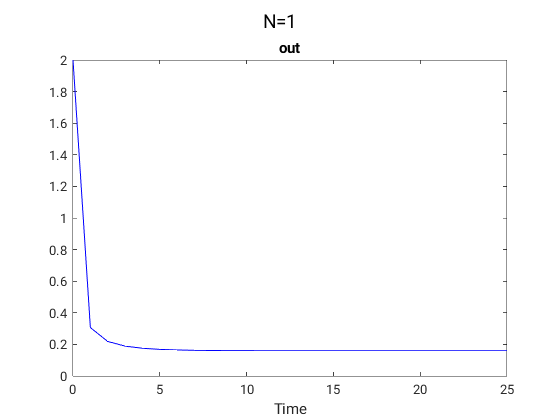

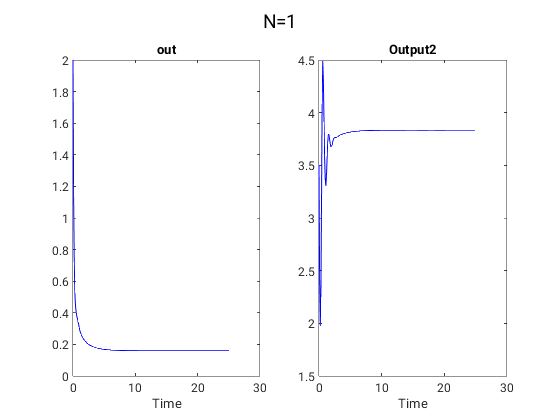

gsua_eval(T.Nominal,T,xdata);

### 1.3 Additional features

#### 1.3.1 Range definition

**Paired feature 'rMethod' (Default rMethod: range)**

You can choose between 4 methods to define the ranges of the model factors, each method requires a different definition of varible **ranges**

- std        <-- {Nominal value,  Distance to interval limits}

- percent <-- {Nominal value,  percent of distance to interval limits}

- range    <-- {Inferior limit, superior limit}

- normal  <-- {Nominal value,  standart deviation}

Examples:

**Note: **The use of normal distribution affects the generation of samples from the space of factors when using the **gsua_dmatrix **function.

**Note: **To fix a factor, give to the function the respective range as a degenerated one (min=max). As you can see, fixed factors will not appear in table **T **(see previous table for R0 factor).

#### 1.3.2 Nominal factor family

You can specify a nominal family of factors values using the **paired feature 'nominal'**. It could be useful for some toolbox functions.

Example:

#### 1.3.3 Specific model output (Default: 1:model_order)

You can specify the output(s) of interest for the model as an array (it should be only one output for **SA, **and **UCI**) using the **paired feature 'output'**.

Example:

#### 1.3.4 Specific names for model factors (Default: {})

You can specify the names of the model factors as an array using the **paired feature 'names'. **The names of the factors are displayed when plotting some graphs.

Example:

#### 1.3.5 Specific names for model outputs (Default: {})

You can specify the names of the model output(s) as an array using the **paired feature 'out_names'. **The names of the outputs are displayed when plotting some graphs.

Example:

#### 1.3.6 Run as vectorized function (Default: false)

If you have a vectorized function, then you can exploit its capabilities using the **paired feature 'vectorized'**

Example:

#### 1.3.7 Any additional user-provided configuration (Default: {})

If your function requires on three inputs, then the third input must be for additional configuration. You can provide anything you want for this function input using the **paired feature 'opt'**

**Example:**

## 2. Time-free functions

### 2.1 Model creation

Time-free functions must be configured in the form **output=user_function(factors)**. Where:

**Parameters:**

- factors: a vector that contains all the parameters needed to run the function

**Output:**

- A numerical array (if vectorized) or a single number.

**Tip: **If your model is time-free but its output is a vector, treat it as a time-dependent model. Just ignore the domain input inside the function.

#### 1.1.1 Example

### 2.2 Model implementation

To prepare the environment to work with time-free user-defined functions, you must run the following code, replacing input parameters as indicated

Parameters:

- Function: Is the name of the user-defined function as char ('my_function')

- Ranges: Numerical array of **Np**x**2**

Outputs:

- T: table array with all required system information

- solver: function handle for simulations (not necessary)

func='user_free';
range=[0 4; 0 4; 0 1; 0 1; 1 2; 0 0.3; 0 1; 0 0.1];
[T,sol]=gsua_dataprep(func,range)

Setting environment to work with user-defined function


T = 8×2 table
          Range      Nominal
         ________    _______

    1    0      4        2  
    2    0      4        2  
    3    0      1      0.5  
    4    0      1      0.5  
    5    1      2      1.5  
    6    0    0.3     0.15  
    7    0      1      0.5  
    8    0    0.1     0.05  


sol = function_handle with value:
    @(pars)user_func(pars')


### 2.3 Additional features

For additional features see Time-dependent features

Return to main page

Go to next toolbox features